% 负荷和DRE数据来自南通
addpath 'D:\OneDrive\Papers\08A probability approach of loss estimation\[Power System]Medium Voltage Distribution Network’s Energy Loss Through Gaussian Mixture Model'
load Nantongdata.mat 
IndoneH = data(:,1); % 工业负荷
ResdataoneH = data(:,2); % 居民负荷
ComoneH = data(:,3);% 商业负荷
Soldata = data(:,4)/(max(data(:,4))); % 光伏
Winddata = data(:,5)/(max(data(:,5))); % 风电

% POT是超阈值分布，要先设定阈值。这里以10%和90%分位点为例
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
q_lo = 0.1;
q_up = 0.9;
q_lo_Ind = quantile(IndoneH,q_lo); % 取工业负荷数据下分位点
q_up_Ind = quantile(IndoneH,q_up); % 取上分位点
q_up_Res = quantile(ResdataoneH,q_up); % 取上分位点
q_up_Com = quantile(ComoneH,q_up); % 取上分位点
q_lo_Sol = quantile(Soldata,q_lo); % 取光伏数据下分位点
q_up_Sol = quantile(Soldata,q_up); % 取上分位点
q_lo_Win = quantile(Winddata,q_lo); % 取风电数据下分位点
q_up_Win = quantile(Winddata,q_up); % 取上分位点

y_up_Ind = IndoneH(IndoneH>q_up_Ind)-q_up_Ind;
y_up_Res = IndoneH(ResdataoneH>q_up_Res)-q_up_Res;
y_up_Com = IndoneH(ComoneH>q_up_Com)-q_up_Com;
y_up_Sol = Soldata(Soldata>q_up_Sol)-q_up_Sol;
y_lo_Sol = q_lo_Sol-Soldata(Soldata<q_lo_Sol);
y_up_Win = Winddata(Winddata>q_up_Win)-q_up_Win;
y_lo_Win = q_lo_Win-Winddata(Winddata<q_lo_Win);
% 下面拟合GPD参数
full_Ind_pd = paretotails(IndoneH,q_lo,q_up); % 完整的工业负荷概率模型
full_Res_pd = paretotails(ResdataoneH,q_lo,q_up);

full_Com_pd = paretotails(ComoneH,q_lo,q_up);

full_Sol_pd = paretotails(Soldata,q_lo,q_up);

full_Win_pd = paretotails(Winddata,q_lo,q_up);

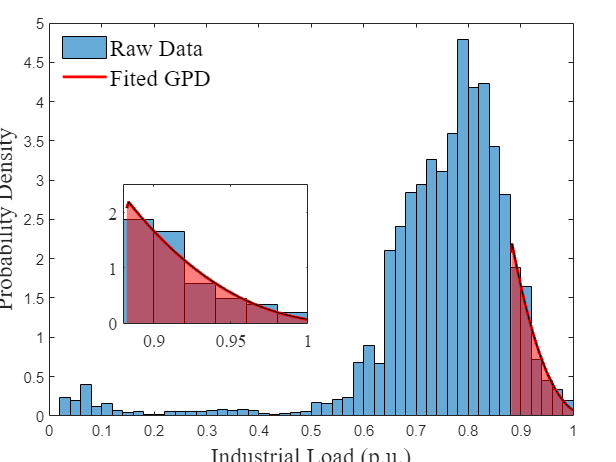

% 这里可能会有warning,摘录一下Matlab的解释:
% GP 分布定义为 0 < sigma,-Inf < k < Inf。然而,当 k < -1/2 时,最大似然估计结果的解释存在问题。
% 幸运的是，这些情况对应于 beta 或三角等分布的尾部拟合，所以这里不会出现问题。

% 节点注入功率的GPD
pd_Ind_up_k = full_Ind_pd.UpperParameters(1); pd_Ind_up_s = full_Ind_pd.UpperParameters(2);
pd_Ind_lo_k = full_Ind_pd.LowerParameters(1); pd_Ind_lo_s = full_Ind_pd.LowerParameters(2);
pd_Res_up_k = full_Res_pd.UpperParameters(1); pd_Res_up_s = full_Res_pd.UpperParameters(2);
pd_Res_lo_k = full_Res_pd.LowerParameters(1); pd_Res_lo_s = full_Res_pd.LowerParameters(2);
pd_Com_up_k = full_Com_pd.UpperParameters(1); pd_Com_up_s = full_Com_pd.UpperParameters(2);
pd_Com_lo_k = full_Com_pd.LowerParameters(1); pd_Com_lo_s = full_Com_pd.LowerParameters(2);
pd_Sol_up_k = full_Sol_pd.UpperParameters(1); pd_Sol_up_s = full_Sol_pd.UpperParameters(2);
pd_Sol_lo_k = full_Sol_pd.LowerParameters(1); pd_Sol_lo_s = full_Sol_pd.LowerParameters(2);
pd_Win_up_k = full_Win_pd.UpperParameters(1); pd_Win_up_s = full_Win_pd.UpperParameters(2);
pd_Win_lo_k = full_Win_pd.LowerParameters(1); pd_Win_lo_s = full_Win_pd.LowerParameters(2);
% 绘制原始数据的PDF和CDF
% 然后叠加我们估计的 GPD的PDF和CDF
myfun1 = @(x)ksdensity(x,'Bandwidth',.01,'Function','cdf');
plot_Ind_pd = paretotails(IndoneH,q_lo,q_up,myfun1);
% 这个图较为复杂，内含一个小图用于放大尾部的图像
figure;
h1=axes('position',[0.08 0.1 0.85 0.85]); % 创建一个坐标系
axes(h1);     %将h1设置为当前坐标系，为绘图准备
histogram(IndoneH,'Normalization','pdf')
hold on
plot(linspace(q_up_Ind,1),pdf(plot_Ind_pd,linspace(q_up_Ind,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Ind,1),pdf(plot_Ind_pd,linspace(q_up_Ind,1)),'FaceColor','red','FaceAlpha',0.5)
axis(h1,[0,1,0,5]); % 坐标轴范围
legend('Raw Data','Fited GPD','Location','best','FontSize',16,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Industrial Load (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Probability Density",'FontSize',16,'Fontname', 'Times New Roman')
hold off
% 在原图上插入一个新的小图
h2=axes('Position',[0.2 0.3 0.3 0.3]);
axes(h2);                  % 将h2设置为当前坐标系
histogram(IndoneH,'Normalization','pdf')
hold on
plot(linspace(q_up_Ind,1),pdf(plot_Ind_pd,linspace(q_up_Ind,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Ind,1),pdf(plot_Ind_pd,linspace(q_up_Ind,1)),'FaceColor','red','FaceAlpha',0.5)
set(h2,'xlim',[0.88 1],'ylim',[0 2.5],'FontSize',12,'Fontname', 'Times New Roman');
hold off

myfun1 = @(x)ksdensity(x,'Bandwidth',.01,'Function','cdf');
plot_Res_pd = paretotails(ResdataoneH,q_lo,q_up,myfun1);

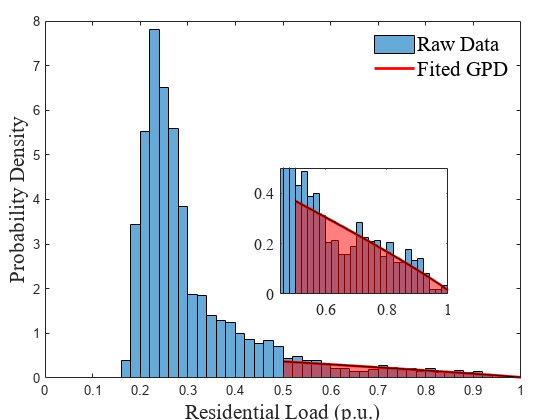


% 这个图较为复杂，内含一个小图用于放大尾部的图像
figure;
h1=axes('position',[0.08 0.1 0.85 0.85]); % 创建一个坐标系
axes(h1);     %将h1设置为当前坐标系，为绘图准备
histogram(ResdataoneH,'Normalization','pdf')
hold on
plot(linspace(q_up_Res,1),pdf(plot_Res_pd,linspace(q_up_Res+0.01,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Res,1),pdf(plot_Res_pd,linspace(q_up_Res+0.01,1)),'FaceColor','red','FaceAlpha',0.5)
axis(h1,[0,1,0,8]); % 坐标轴范围
legend('Raw Data','Fited GPD','Location','best','FontSize',16,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Residential Load (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Probability Density",'FontSize',16,'Fontname', 'Times New Roman')
hold off
% 在原图上插入一个新的小图
h2=axes('Position',[0.5 0.3 0.3 0.3]);
axes(h2);                  % 将h2设置为当前坐标系
histogram(ResdataoneH,'Normalization','pdf')
hold on
plot(linspace(q_up_Res,1),pdf(plot_Res_pd,linspace(q_up_Res+0.01,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Res,1),pdf(plot_Res_pd,linspace(q_up_Res+0.01,1)),'FaceColor','red','FaceAlpha',0.5)
set(h2,'xlim',[0.45 1],'ylim',[0 0.5],'FontSize',12,'Fontname', 'Times New Roman');
hold off

myfun1 = @(x)ksdensity(x,'Bandwidth',.01,'Function','cdf');
plot_Com_pd = paretotails(ComoneH,q_lo,q_up,myfun1);

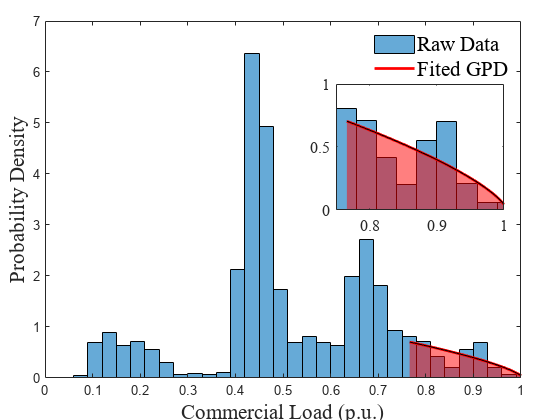


% 这个图较为复杂，内含一个小图用于放大尾部的图像
figure;
h1=axes('position',[0.08 0.1 0.85 0.85]); % 创建一个坐标系
axes(h1);     %将h1设置为当前坐标系，为绘图准备
histogram(ComoneH,'Normalization','pdf')
hold on
plot(linspace(q_up_Com,1),pdf(plot_Com_pd,linspace(q_up_Com,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Com,1),pdf(plot_Com_pd,linspace(q_up_Com,1)),'FaceColor','red','FaceAlpha',0.5)
axis(h1,[0,1,0,7]); % 坐标轴范围
legend('Raw Data','Fited GPD','Location','best','FontSize',16,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Commercial Load (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Probability Density",'FontSize',16,'Fontname', 'Times New Roman')
hold off
% 在原图上插入一个新的小图
h2=axes('Position',[0.6 0.5 0.3 0.3]);
axes(h2);                  % 将h2设置为当前坐标系
histogram(ComoneH,'Normalization','pdf')
hold on
plot(linspace(q_up_Com,1),pdf(plot_Com_pd,linspace(q_up_Com,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Com,1),pdf(plot_Com_pd,linspace(q_up_Com,1)),'FaceColor','red','FaceAlpha',0.5)
set(h2,'xlim',[0.75 1],'ylim',[0 1],'FontSize',12,'Fontname', 'Times New Roman');
hold off

myfun1 = @(x)ksdensity(x,'Bandwidth',.01,'Function','cdf');
plot_Sol_pd = paretotails(Soldata,q_lo,q_up,myfun1);

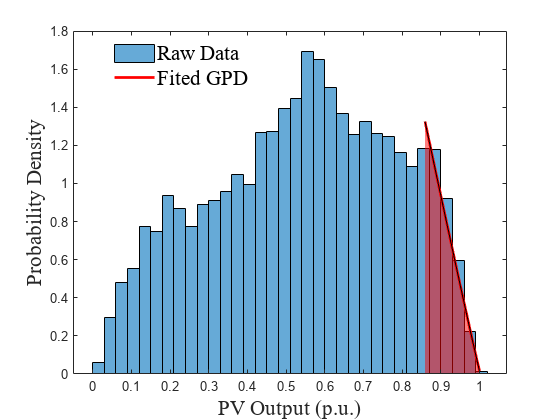

figure;
histogram(Soldata,'Normalization','pdf')
hold on
plot(linspace(q_up_Sol,1),pdf(plot_Sol_pd,linspace(q_up_Sol+0.01,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Sol,1),pdf(plot_Sol_pd,linspace(q_up_Sol+0.01,1)),'FaceColor','red','FaceAlpha',0.5)
legend('Raw Data','Fited GPD','Location','best','FontSize',16,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("PV Output (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Probability Density",'FontSize',16,'Fontname', 'Times New Roman')
hold off

myfun1 = @(x)ksdensity(x,'Bandwidth',.01,'Function','cdf');
plot_Win_pd = paretotails(Winddata,q_lo,q_up,myfun1);

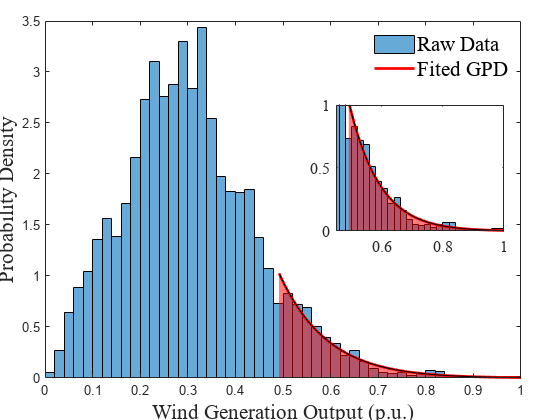

% 这个图较为复杂，内含一个小图用于放大尾部的图像
figure;
h1=axes('position',[0.08 0.1 0.85 0.85]); % 创建一个坐标系
axes(h1);     %将h1设置为当前坐标系，为绘图准备
histogram(Winddata,'Normalization','pdf')
hold on
plot(linspace(q_up_Win,1),pdf(plot_Win_pd,linspace(q_up_Win,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Win,1),pdf(plot_Win_pd,linspace(q_up_Win,1)),'FaceColor','red','FaceAlpha',0.5)
axis(h1,[0,1,0,3.5]); % 坐标轴范围
legend('Raw Data','Fited GPD','Location','best','FontSize',16,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Wind Generation Output (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Probability Density",'FontSize',16,'Fontname', 'Times New Roman')
hold off
% 在原图上插入一个新的小图
h2=axes('Position',[0.6 0.45 0.3 0.3]);
axes(h2);                  % 将h2设置为当前坐标系
histogram(Winddata,'Normalization','pdf')
hold on
plot(linspace(q_up_Win,1),pdf(plot_Win_pd,linspace(q_up_Win,1)),'r-','LineWidth',2)
hold on 
area(linspace(q_up_Win,1),pdf(plot_Win_pd,linspace(q_up_Win,1)),'FaceColor','red','FaceAlpha',0.5)
set(h2,'xlim',[0.45 1],'ylim',[0 1],'FontSize',12,'Fontname', 'Times New Roman');
hold off

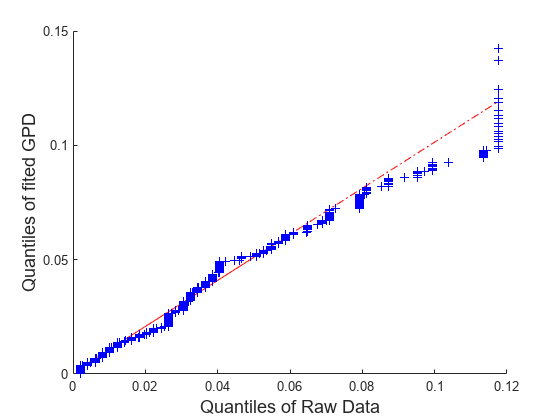

figure;
qqplot(y_up_Ind,gprnd(pd_Ind_up_k,pd_Ind_up_s,0,[1000,1]));
xlabel("Quantiles of Raw Data",'FontSize',14)
ylabel("Quantiles of fited GPD",'FontSize',14)

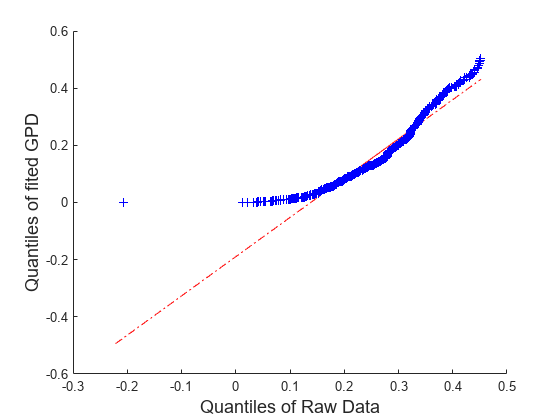

figure;
qqplot(y_up_Res,gprnd(pd_Res_up_k,pd_Res_up_s,0,[1000,1]));
xlabel("Quantiles of Raw Data",'FontSize',14)
ylabel("Quantiles of fited GPD",'FontSize',14)

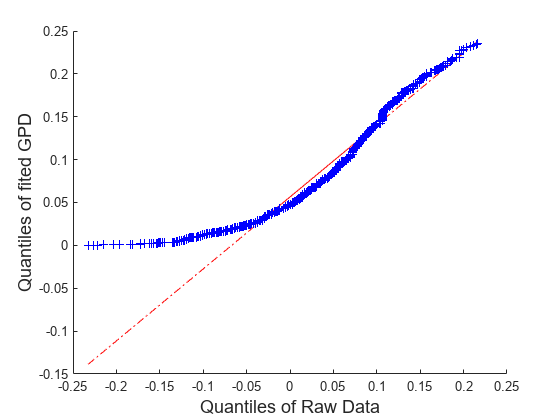

figure;
qqplot(y_up_Com,gprnd(pd_Com_up_k,pd_Com_up_s,0,[1000,1]));
xlabel("Quantiles of Raw Data",'FontSize',14)
ylabel("Quantiles of fited GPD",'FontSize',14)

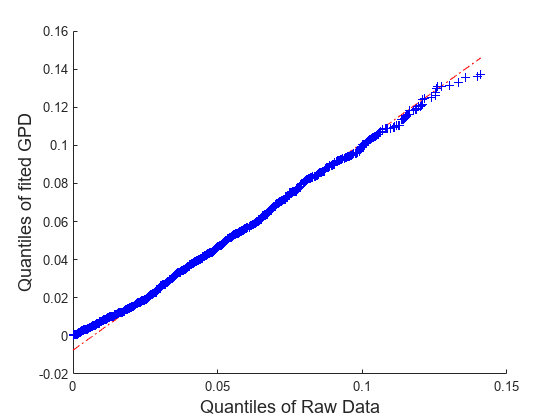

figure;
qqplot(y_up_Sol,gprnd(pd_Sol_up_k,pd_Sol_up_s,0,[1000,1]));
xlabel("Quantiles of Raw Data",'FontSize',14)
ylabel("Quantiles of fited GPD",'FontSize',14)

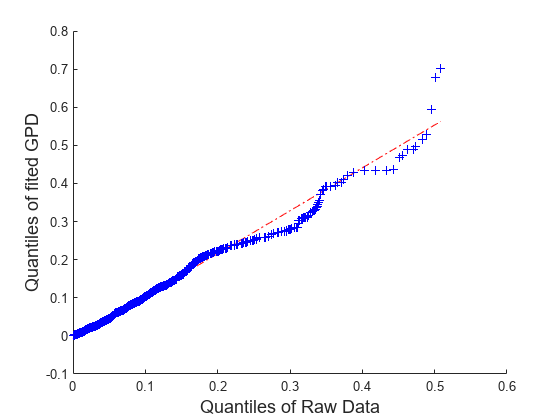

figure;
qqplot(y_up_Win,gprnd(pd_Win_up_k,pd_Win_up_s,0,[1000,1]));
xlabel("Quantiles of Raw Data",'FontSize',14)
ylabel("Quantiles of fited GPD",'FontSize',14)